%% Simulation of a 1 virtual leader and 2 two-wheeled mobile robot with Control and trajectory following
clear all 
clc
close all 


%% simulation parameter
total_time = 15;  % (seconds)
dt = 0.1; % step sizes
time_stamp = total_time/dt; % simulation time
i = 1; % to start while loop


%% mobile robot parameter and initial contitions
v_i = [0; 0; 0]; % initial linear velocity of a followers (ignore first index)
w_i = [0; 0; 0]; % initial angular velocity of a followers (ignore first index)

%% Virtual Leader Parameters
x_pos_v = zeros(3, time_stamp); % store the position
point_v = [5;5;0]; % starting point and orientation
v_r = 1; % virtual linear velocity
w_r = pi/6; % virtual angular velocity

%% Robot 1 (follower) parameters
x_pos_1 = zeros(3, time_stamp); % store the position
point_1 = [8;8;(3*pi/2)];  % starting point and orientation

%% Robot 2 (follower) parameters 
x_pos_2 = zeros(3, time_stamp); % store the position
point_2 = [12;13;(3*pi/2)]; % starting point and orientation

%% Combine Robot Parameters
x_pos(:,:,1) = x_pos_v;
x_pos(:,:,2) = x_pos_1;
x_pos(:,:,3) = x_pos_2;

point(:,:,1) = point_v;
point(:,:,2) = point_1;
point(:,:,3) = point_2;

%% To store the error values
er = zeros(3, 3);

%% Target positions for the followers
target_r_1 = point_v + [0;-1;0];  
target_r_2 = target_r_1 + [0;-1;0]; 


%% k parameters for control
k1 = 2; % TODO -> tune for better results
k2 = 0.1; % TODO -> tune for better results
k3 = 2; % TODO -> tune for better results

%% init for following trajectory algorithm
x = 0;
y = 0;
e = [10; 10; 10];

%% loop starts here
while i <= time_stamp
    x_pos(:,i,1) = point(:,:,1);
    q_dot = model(point(3,:,1),v_r,w_r); % time derivative of position
    point(1:2,:,1) = point(1:2,:,1) + q_dot(1:2) * dt; % state (position) update
    point(3,:,1) = point(3,:,1) + q_dot(3) * dt; % state (orientation) update
    for j = 2:3 % simulate the followers here 
        x_pos(:,i,j) = point(:,:,j); % take the position values for followers according to the error
        q_dot(:,:,j) = model(point(3,j),v_i(j),w_i(j));
        point(1:2,j) = point(1:2,j) + q_dot(1:2,j) * dt;
        point(3,j) = point(3,j) + q_dot(3,j) * dt;
        if j == 2 % for 1st follower
            e = error_function(target_r_1(1),target_r_1(2),target_r_1(3),point(1,:,j),point(2,:,j),point(3,:,j));
            er(:,j) = e;
            err(:,i,1) = e;
            v_i(j) = v_r * cos(er(3,j)) + k1 * er(1,j);
            w_i(j) = w_r + (k2 * er(2,j) + (k3 *er(3,j)));
            if norm(e(1:2)) < 0.6 | x == 1 % if it goes to the desired point start to follow same trajectory as virtual leader
                err(:,i,1) = 0;
                v_i(j) = v_r;
                w_i(j) = w_r;
                x = 1;
            end
        else  % for second follower
            e = error_function(target_r_2(1),target_r_2(2),target_r_2(3),point(1,:,j),point(2,:,j),point(3,:,j));
            er(:,j) = e;
            err(:,i,2) = e;
            v_i(j) = v_r * cos(er(3,j)) + k1 * er(1,j);
            w_i(j) = w_r + (k2 * er(2,j) + (k3*er(3,j)));
            if norm(e(1:2)) < 1.9 | y == 1 % if it goes to the desired point start to follow same trajectory as virtual leader
                err(:,i,2) = 0;
                v_i(j) = v_r;
                w_i(j) = w_r;
                y = 1;
            end
        end
        %disp(point)
    end
    time(i) = i/10;
    i = i + 1;
end

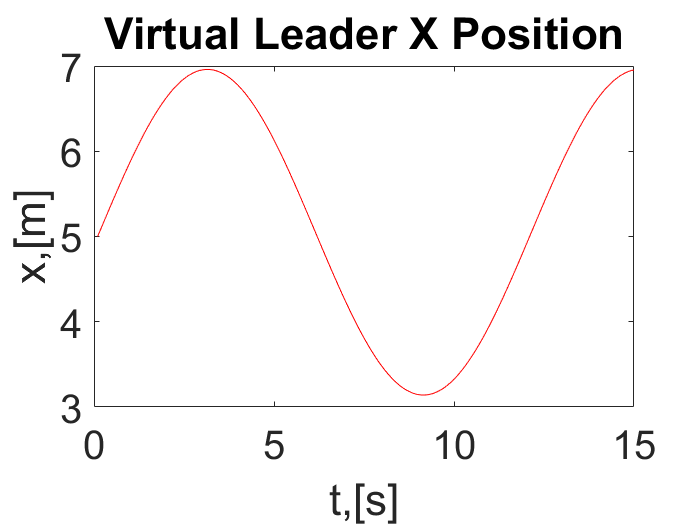

% plotting functions
figure
plot(time, x_pos(1,:,1),'r');
set(gca, 'fontsize',24)
xlabel('t,[s]');
ylabel('x,[m]');
title("Virtual Leader X Position")

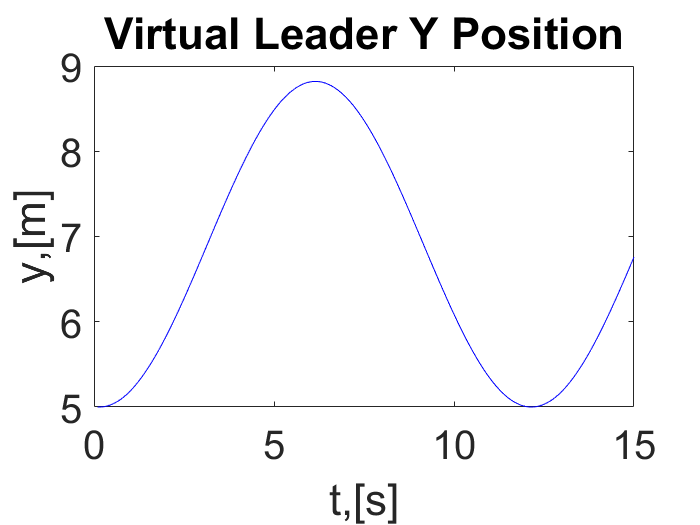


%
figure
plot(time, x_pos(2,:,1),'b-');
set(gca,'fontsize',24);
xlabel('t,[s]');
ylabel('y,[m]');
title("Virtual Leader Y Position")

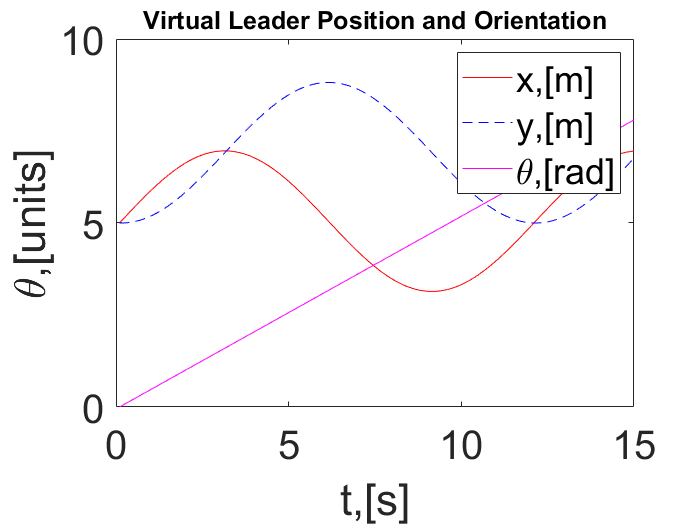

figure
plot(time, x_pos(1,:,1),'r');
hold on
plot(time, x_pos(2,:,1),'b--');
plot(time, x_pos(3,:,1),'m');
legend('x,[m]','y,[m]','\theta,[rad]');
set(gca,'fontsize',24)
xlabel('t,[s]');
ylabel('\theta,[units]');
title("Virtual Leader Position and Orientation",'FontSize',15)

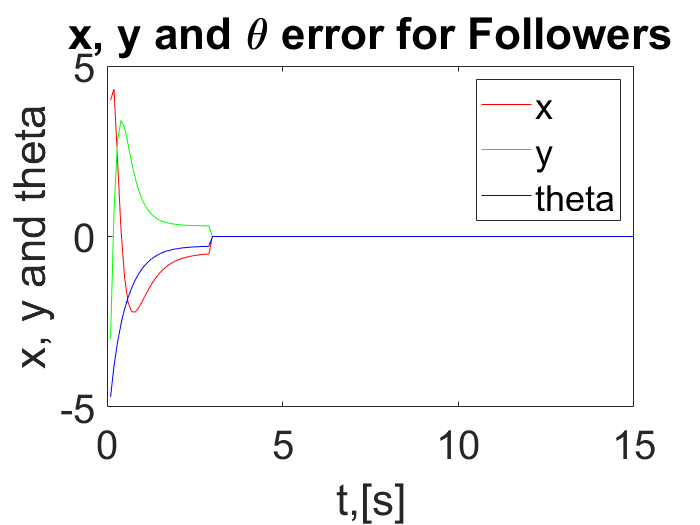

figure
plot(time, err(1,:,1),'r');
hold on
plot(time, err(2,:,1),'g')
hold on
plot(time, err(3,:,1),'b')
set(gca, 'fontsize',24)
xlabel('t,[s]');
ylabel('x, y and theta');
title("x, y and \theta error for Followers")
legend("x", "y","theta")

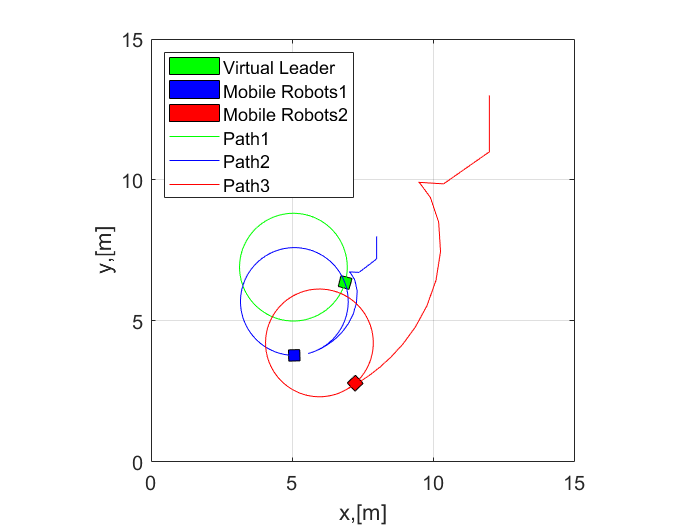


%% Animation (mobile robot motion animation)
l = 0.4; % length of the mobile robot
w = 0.4; % width of the mobile robot
% Mobile robot cooridinates
box_v = [-l/2,l/2,l/2,-l/2,-l/2;
         -w/2,-w/2,w/2,w/2,-w/2;];   
figure
for i = 1:5:(length(time)-1)
    theta_v = x_pos(3,i,1);
    R_theta_v = [cos(theta_v), -sin(theta_v);
               sin(theta_v), cos(theta_v);]; % rotation matrix
    v_pos_v = R_theta_v*box_v;

    theta_1 = x_pos(3,i,2);
    R_theta_1 = [cos(theta_1), -sin(theta_1);
               sin(theta_1), cos(theta_1);]; % rotation matrix
    v_pos_1 = R_theta_1*box_v;

    theta_2 = x_pos(3,i,3);
    R_theta_2 = [cos(theta_2), -sin(theta_2);
               sin(theta_2), cos(theta_2);]; % rotation matrix
    v_pos_2 = R_theta_2*box_v;

    fill(v_pos_v(1,:)+x_pos(1,i,1),v_pos_v(2,:)+x_pos(2,i,1),'g','DisplayName','Virtual Leader');
    hold on
    fill(v_pos_1(1,:)+x_pos(1,i,2),v_pos_1(2,:)+x_pos(2,i,2),'b','DisplayName','Mobile Robots1');
    hold on
    fill(v_pos_2(1,:)+x_pos(1,i,3),v_pos_2(2,:)+x_pos(2,i,3),'r','DisplayName','Mobile Robots2');
    hold on, grid on
    axis([0 15 0 15]), axis square
    plot(x_pos(1,1:i,1),x_pos(2,1:i,1),'green','DisplayName','Path1');
    plot(x_pos(1,1:i,2),x_pos(2,1:i,2),'blue','DisplayName','Path2');  
    plot(x_pos(1,1:i,3),x_pos(2,1:i,3),'red','DisplayName','Path3');  
    set(gca, 'fontsize',12)
    xlabel('x,[m]'); ylabel('y,[m]');
    pause(0.01)
    grid on
    hold off
end % animation ends here
legend('Location',"northwest")